# 15 Fundamentals of Algorithms for Nonlinear Constrained Optimization

In this Chapter we study the constrained optimization problem

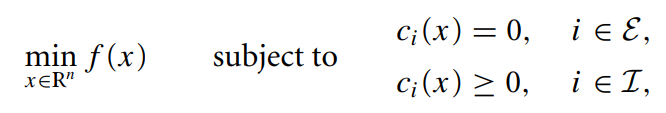

where

- $f, c_i: C\subseteq\mathbb{R}^2\to \mathbb{R}$ are smooth functions

- $\mathcal{E}$ and $\mathcal{I}$ are finite index sets.

**Remark:**

- This chapter is not concerned with individual algorithms themselves, but rather with **fundamental concepts** and **building blocks **that are common to more than one algorithm

## 15.1 CATEGORIZING OPTIMIZATION ALGORITHMS

    🔸 Freedom elimination algorithms 

- Algorithms for quadratic programming (chap 16): Basic algorithms for many other methods 

- Sequential quadratic programming method (chap 18): Active set methods 

- Interior point methods, barrier methods (chap 19)

    🔸 Merit functions and filters 

- Penalty and augmented Lagrangian methods (chap 17) 

- Filters, and non monotone methods (this chap)

## 15.2 THE COMBINATORIAL DIFFICULTY OF INEQUALITY-CONSTRAINED PROBLEMS 

**Active set methdos:**

Recall:

The optimal active set $\mathcal{A}^*$  is the set of constraints that are satisfied as equalities at a solution.

- Starts by making a guess of the optimal active set $\mathcal{A}^*$.

- This guess will be denoted by $\mathcal{W}$ and is called the **working set**.

- We then solve a problem in which the constraints in the working set are imposed as equalities and the constraints not in  $\mathcal{W}$ are ignored

- We then check to see if there is a choice of Lagrange multipliers such that the solution $x^\ast $ obtained for this $\mathcal{W}$ satisfies the KKT conditions.

-  If so, we accept $x^\ast $ as a local solution. Otherwise, we make a different choice of $\mathcal{W}$ and repeat the process.

**Problem:**

- The number of choices for working set $\mathcal{W}$ may be very large—up to $2^{|\mathcal{I}|}$ , where $|\mathcal{I}|$ is the number of inequality constraints. 

- Since the number of possible working sets grows exponentially with the number of inequalities—a phenomenon which we refer to as **the combinatorial difficulty of nonlinear programming**

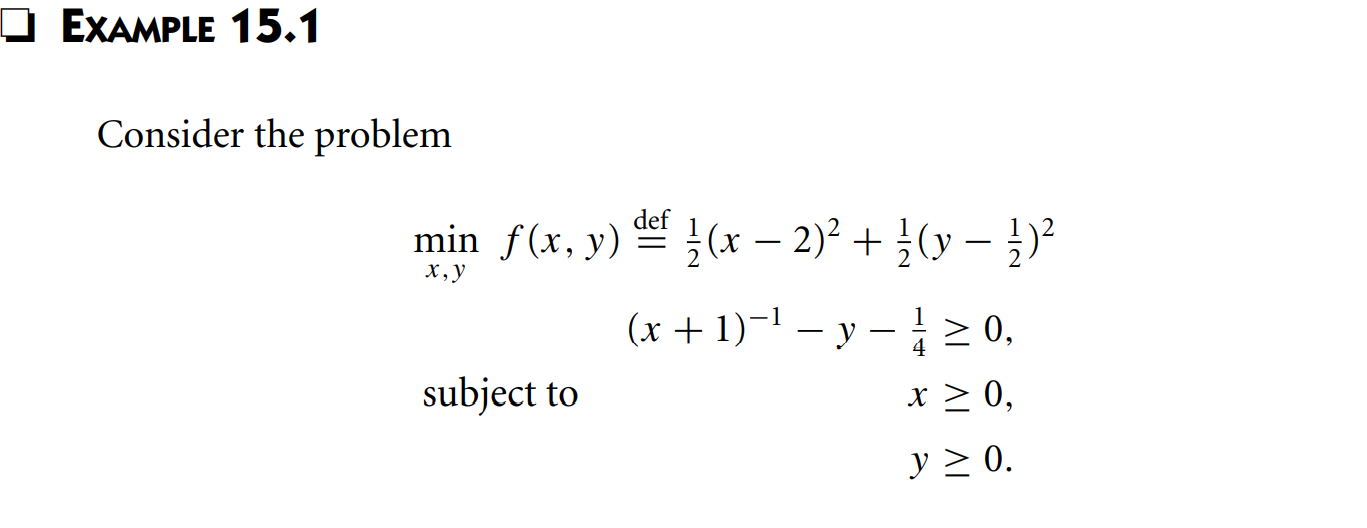

 **Solution in Class**

clearvars
syms x real positive
eq = (x-2)*(x+1)^3+(3/4)*(x+1)-1 == 0

$$eq = \frac{3\,x}{4}+{\left(x+1\right)}^{3}\,\left(x-2\right)-\frac{1}{4}=0$$

xval = double(vpa(solve(eq,x)))

xval = 1.9528

yval  = -0.25 + 1/(xval+1) 

yval = 0.0887

lambda = -yval + 0.5

lambda = 0.4113

% 

## 15.3 ELIMINATION OF VARIABLES

- We need to be careful when we eliminate variables.

- We do this when it is safe (**Example)**

- Use of nonlinear equations to eliminate variables may result in errors that can be difficult to trace

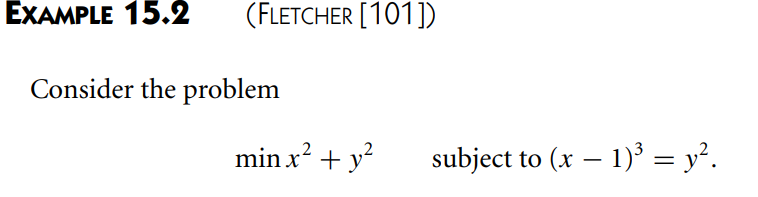

**SOLUTION IN CLASS:**

### SIMPLE ELIMINATION USING LINEAR CONSTRAINTS 

Let  $AP = \left[B\; | \; N\right],$ and $\left[x_B, x_N\right]^T = P^Tx$ where

- $B$ is an $m\times m$ matrix of linearly independent columns of $A$.

- $P$ is an $n\times n$ permutation matrix that swaps these columns to the first $m$ column positions in $A$.

- $N$ is the $n-m$ remaining columns of $A$.

- $x_B$ is the basic variables.

So 

$b = Ax =APP^Tx =Bx_B + Nx_N$, 

therefore, 


$$x_B = B^{-1}b - B^{-1}Nx_N$$


This substitution is called  **simple elimination of variables**.

It gives us the unconstrained problem

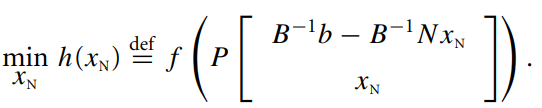

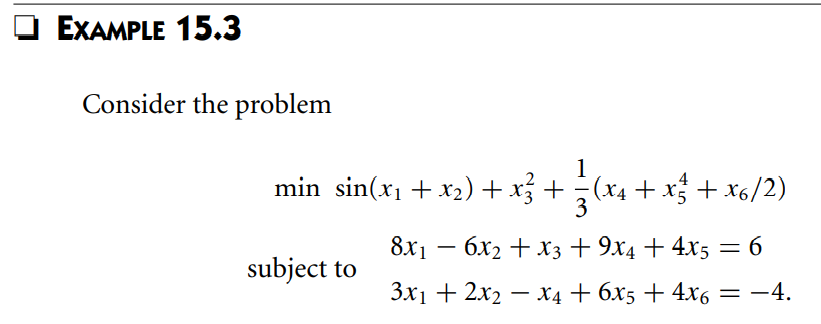

**SOLUTION IN CLASS**

#### Interpretation

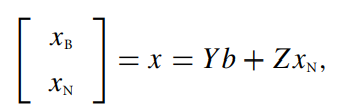 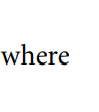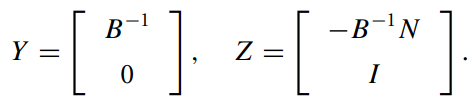

- $Z$ has $n-m$ linearly independent columns.

- $AZ=0$, so $Z$ is a basis for the null space of $A$.

- The columns of $Y$ and the columns of $Z$ form a linearly independent set.

We can therefore see that the simple elimination technique expresses feasible points as the sum of 

- a particular solution of $Ax= b$

- plus  a displacement along the null space of the constraints

- The particular solution $Y b$ is sometimes known as the **coordinate relaxation step**.

- Simple elimination is inexpensive but can give rise to numerical instabilities.

- Selection of the best basis is, therefore, not a straightforward task in general. 

- To overcome the dangers of an excessively large coordinate relaxation step, we could define the particular solution $Y b$ as the minimum-norm step to the constraints. 

### GENERAL REDUCTION STRATEGIES FOR LINEAR CONSTRAINTS

Choose $Y\in \mathbb{R}^{n\times m}$ and $Z\in \mathbb{R}^{n\times (n-m)}$ such that

 $\left[Y\; | \; Z\right]\in \mathbb{R}^{n\times n}$ is nonsingular, $AZ=0$.

### MERIT FUNCTIONS AND FILTERS 

- Write a constrained problem as an unconstrained one.

- This problem minimizes the objective function and increases the voilation of the constraints.

We can achieve this by 

- Merit functions

- Filters

**Merit Functions**

    One choice is the $\ell _1$ penalty function defined by

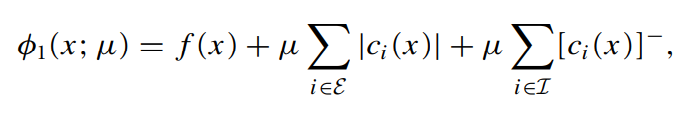

where

- 
$$[z]^-=\max\{0,-z\}$$


- $\mu$ is the **penalty paramete **